# Datasets y Visualización

Vamos a aprender a manejar muchos datos, cómo limpiarlos y demás.

Clonamos un repositorio desde Github.

Vimos brevemente los tipos de variables que podemos usar en Matlab (no siempre son puras matrices).

## Importar con Readtable y Readmatrix

%readmatrix
area_mm = readmatrix("D:\Documents\UNAM\Semestre 6\A&P_Señales\Prácticas\Utils4SP\Datasets\areaMM", 'Delimiter', '  ')

area_mm =   340.4277  324.3750  308.9114  293.6813  277.8073  261.0772  245.9019  232.8705  218.6999  203.1390  189.3382  176.6128  169.5532  168.8775  172.0049  174.4247  178.4295  183.9891  193.8382  206.2434  219.7135  234.3422  248.6808  263.1539  276.9246  293.0711  308.6514  324.5290  339.1647  348.7149  354.1932  356.6855  356.3495  354.7398  355.8347  358.5429  363.1208  370.1026  377.4434  387.1900  396.7827  403.9608  411.5069  420.4716  429.3214  439.3651  448.8747  459.0157  469.0630  478.9387



%readtable
PSD_bands=readtable("D:\Documents\UNAM\Semestre 6\A&P_Señales\Prácticas\Utils4SP\Datasets\2021.10.04_IntensidadBobinas.xlsx")

PSD_bands = 630×13 table
    Dist_cm_    PSD_B1      PSD_B2        PSD_B3       PSD_B4       PSD_B5      PSD_B6      PSD_B7       PSD_B8       PSD_B9       PSD_B10      PSD_B11     PSD_Base 
    ________    _______    _________    __________    _________    _________    _______    _________    _________    _________    _________    _________    _________

      0.5       0.54799     0.012948     0.0051533    0.0046358     0.020502     1.1388     0.010652    0.0029874    0.0060306    0.0044177    0.0027482     0.008748
      0.5       0.50418    0.00171

%sólo en esta tabla tenemos 8190 entradas y se cargaron muy rápido 

%Pasa sonda Casssini
Cassini=importfile_cassini("D:\Documents\UNAM\Semestre 6\A&P_Señales\Prácticas\Utils4SP\Datasets\05358_mrdcd_sdfgmc_krtp_1s.asc")

Cassini = 86136×8 table
           FechaHora            Bx_nt     By_nt     Bz_nt     Bmag_nt       X_km           Y_km         Z_km  
    _______________________    _______    ______    ______    _______    ___________    ___________    _______

    2005 12 24 00 00 01 500    -2.7452    5.0172    1.3641    5.8797     -4.6408e+05    -5.8423e+05    -5057.4
    2005 12 24 00 00 02 500     -2.744    5.0013    1.3821    5.8698     -4.6416e+05    -5.8416e+05    -5057.4
    2005 12 24 00 00 03 500    -2.7611    4.9922     1.362    5.8654     -4.6424e+05    -5.8408e+05    -5057.4
    2005 12 24 00 00 04 500    -2.7872    4.9906    1.3063    5.8637     -4.6433e+05      -5.84e+05    -5057.3
    2005 12 24 00 00 05 500    -2.823

## Importar Audio

[y,fs]=audioread("D:\Documents\UNAM\Semestre 6\A&P_Señales\Prácticas\Utils4SP\Datasets\Owl.wav")

y =    -0.0084   -0.0084
   -0.0085   -0.0085
   -0.0088   -0.0087
   -0.0085   -0.0085
   -0.0083   -0.0083
   -0.0084   -0.0083
   -0.0084   -0.0084
   -0.0088   -0.0088
   -0.0088   -0.0089
   -0.0089   -0.0094


fs = 22050

% Se puede escuchar con:
% sound(y,fs) % el audio se escucha muy fuerte...aguas


## Datastore

Vamos a decirle a Matlab que mantenga una carpeta como fuente de datos que se puede actualizar.

ds=datastore("D:\Documents\UNAM\Semestre 6\A&P_Señales\Prácticas\Utils4SP\Datasets\AtmosferaLogger_V2");

atmosfera=readall(ds);
atmosfera.Properties.VariableNames=["Fecha" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"]

atmosfera = 84572×5 table
           Fecha           Pres_kpa    Temp_C    Hum_perc    Bat_V
    ___________________    ________    ______    ________    _____

    {'210722 22:25:18'}     78.57      27.18       48.4      4.48 
    {'210722 22:25:23'}     78.58      27.35      48.53      4.49 
    {'210722 22:25:28'}     78.58      27.28      48.43      4.46 
    {'210722 22:25:33'}     78.58      27.07      47.98      4.45 
    {'210722 22:25:38'}     78.58      27.01       48.2      4.45 
    {'210722 22:25:43'}     78.59      26.91      47.89      4.49 
    {'210722 22:25:48'}     78.58      26.86      48.72      4.47 
    {'210722 22:25:53'}     78.58      26.81      48.03      4.45 
    {'210722 22:25:58'}     78.58      26.77      48.48      4.48 
    {'210722 22:26:03'}     78.58      26.72       48.3      4.47 

## Reordenando

## Limpieza

Agarramos los datos entre 18-May y 26-May a las 6 pm 

%Elegimos puntos en el timepo para muestrear
%Hasta que no reparemos lo de la fecha y hora en atmosfera esto deberá
%seguir comentado
% T1=datetime(2021,5,18,6,0,0)
% T2=datetime(2021,5,26,6,0,0)
% 
% index=atmosfera.DateTime>T1 & atmosfera.DateTime<T2
% 
% atmosfera_part=atmosfera(index,:);
% 


## Limpieza de Nans

sum( ismissing(atmosfera_part) )

ans =      0     0     0    11    61     0


summary(atmosfera_part)

Variables:

    Fecha: 137522×1 cell array of character vectors

    Hora: 137522×1 cell array of character vectors

    Pres_kpa: 137522×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137522×1 double

        Values:

            Min             13.38  
            Median          21.01  
            Max             100    
            NumMissing      11     

    Hum_perc: 137522×1 double

        Values:

            Min             15.27  
            Median          50.16  
            Max             99.97  
            NumMissing      61     

    DateTime: 137522×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:59:48
            Max       20210526 05:59:55




%Remover filas con NaNs
atmosfera_noNaNs=rmmissing(atmosfera_part)

atmosfera_noNaNs = 137450×6 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc        DateTime     
    __________    ____________    ________    ______    ________    _________________

    {'210518'}    {'06:00:03'}     78.01      14.94      85.27      20210518 06:00:03
    {'210518'}    {'06:00:08'}     78.02      14.96      85.59      20210518 06:00:08
    {'210518'}    {'06:00:13'}     78.01      14.96       85.6      20210518 06:00:13
    {'210518'}    {'06:00:18'}     78.01      14.97      85.31      20210518 06:00:18
    {'210518'}    {'06:00:23'}     78.01      14.98      85.59      20210518 06:00:23
    {'210518'}    {'06:00:28'}     78.01      14.97      85.46      20210518 06:00:28
    {'210518'}    {'06:00:33'}     78.02      14.98      85.44      20210

summary(atmosfera_noNaNs)

Variables:

    Fecha: 137450×1 cell array of character vectors

    Hora: 137450×1 cell array of character vectors

    Pres_kpa: 137450×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137450×1 double

        Values:

            Min        13.38  
            Median     21.01  
            Max        46.86  

    Hum_perc: 137450×1 double

        Values:

            Min         15.27 
            Median     50.155 
            Max         99.97 

    DateTime: 137450×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:57:17
            Max       20210526 05:59:55



## Ploteo Exploratorio

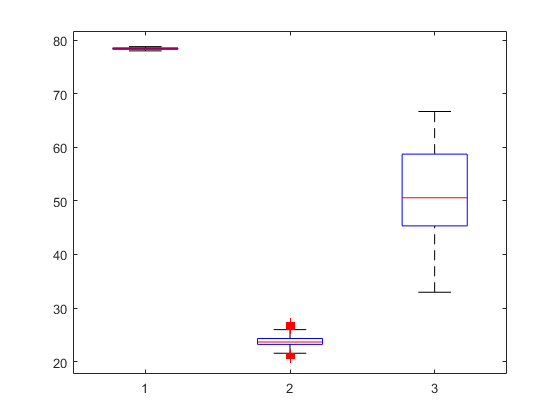

%stackedplot('atmosfera')

figure
boxplot(atmosfera {: , ['Pres_kpa', 'Temp_C' , "Hum_perc"]})

## Histograma

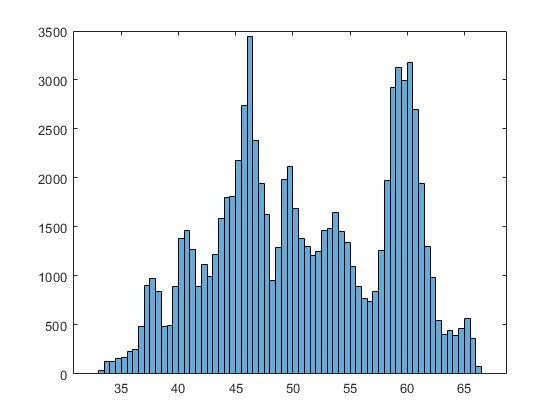

figure
histogram(atmosfera.Hum_perc)

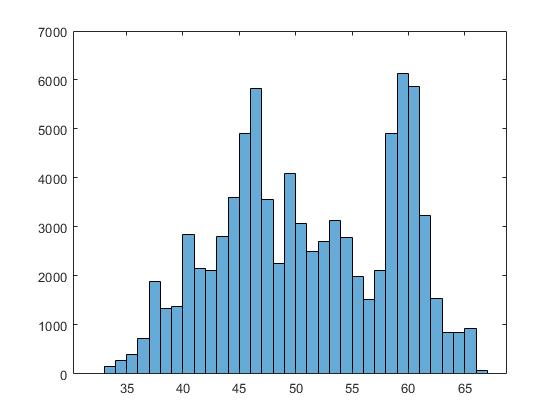


figure
histogram(atmosfera.Hum_perc, 'BinWidth',1)

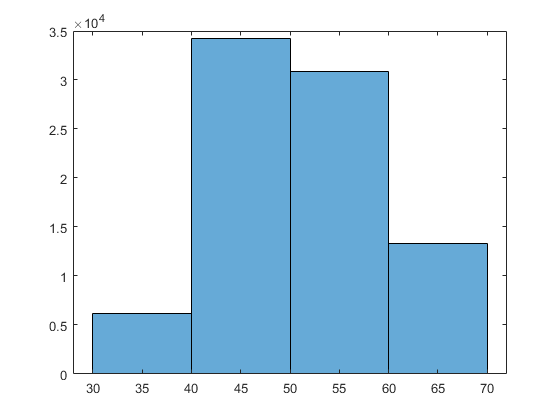


figure
histogram(atmosfera.Hum_perc, 'BinWidth',10)


%Aquí es importante que utilicemos el BinWidth correcto.
%No vayas a abusar del Binwidth para cucharear datos >:(


## Dispersión

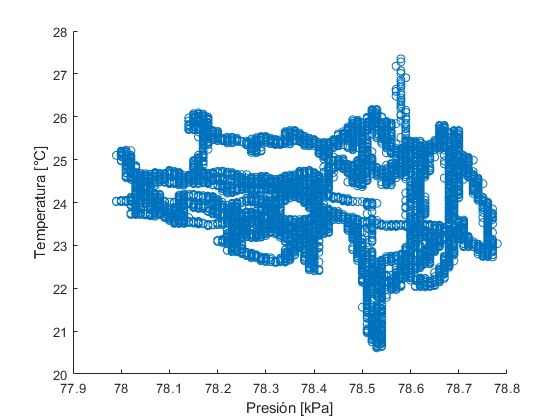

figure
scatter(atmosfera.Pres_kpa,atmosfera.Temp_C)
xlabel("Presión [kPa]")
ylabel("Temperatura [°C]")

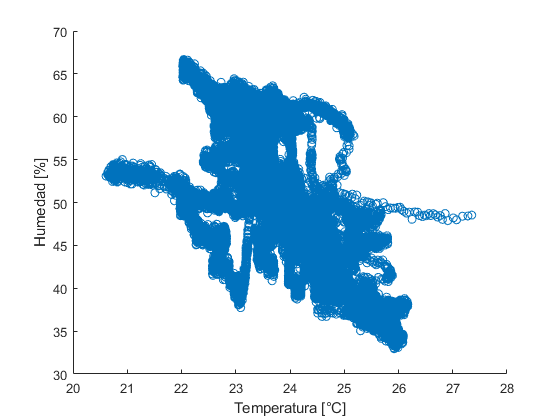

%Felicidades....no hay relacion apreciable jaja

figure
scatter(atmosfera.Temp_C,atmosfera.Hum_perc)
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")

## Plot Matrix

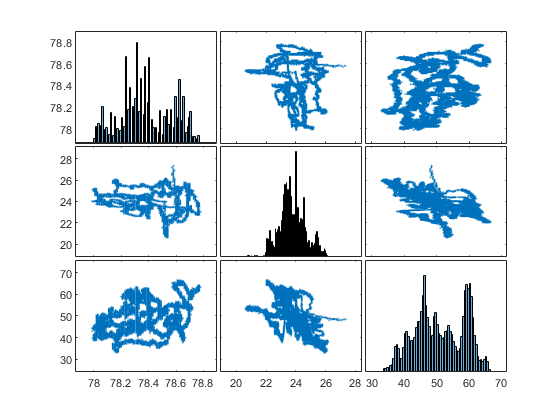

figure
plotmatrix(atmosfera{:,["Pres_kpa" , "Temp_C", "Hum_perc"]})

## Tiled Layout

% %Con estos comandos puedes poner cada gráfica en formato fancy
% %Para presentar pro pues
% 
% tiledlayout("flow")
% % nexttile
% plot(atmosfera.DateTime,atmosfera.Pres_kpa)
% xlabel("Presión [kPa]\sigma")
% ylabel("Fecha")
% 
% nexttile
% plot(atmosfera.Fecha, atmosfera.Temp_C)
% xlabel("Temperatura [°C]")
% ylabel("Fecha")
% 
% nexttile
% plot(atmosfera.Fecha, atmosfera.Hum_perc)
% xlabel("Humedad [%]")
% ylabel("Fecha")



## Agrupacion y orden

Cataloguemos temperaturas (frio entre Temp 1 y Temp 2)

edges=[-30 15 20 55]

edges =    -30    15    20    55



categorias=["Frio" , "Templado" , "Caliente"]

categorias = 1×3 string array
    "Frio"    "Templado"    "Caliente"


%Clasificamos las temperaturas conn categóricos
temp_cats=discretize(atmosfera_noNaNs.Temp_C,edges,'categorical',categorias);

%con este lo agregamos a la tabla original
atmosfera_noNaNs.temp_cats=temp_cats;

%ordenamos:
temp_Descend=sort(atmosfera_noNaNs.Temp_C,'descend')

temp_Descend =    46.8600
   46.7600
   46.7500
   46.6100
   46.4900
   46.3500
   46.3300
   46.1800
   45.9200
   45.7800


temp_Ascend=sort(atmosfera_noNaNs.Temp_C,'ascend')

temp_Ascend =    13.3800
   13.3800
   13.4000
   13.4000
   13.4100
   13.4100
   13.4300
   13.4400
   13.4400
   13.4400


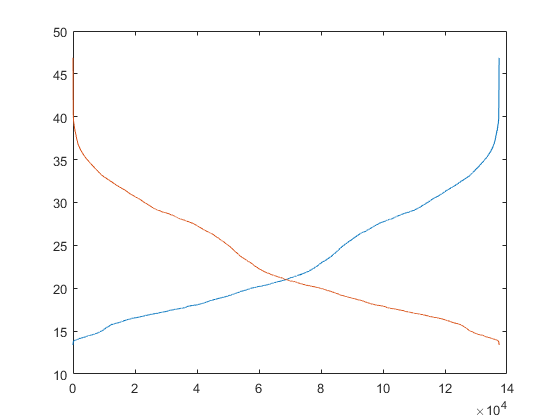


figure
plot([temp_Ascend , temp_Descend])

## G scatter

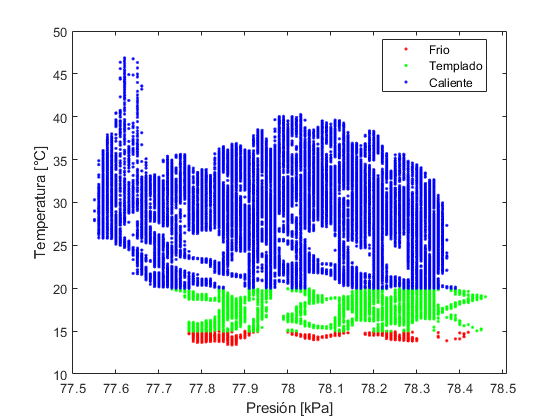

figure
gscatter(atmosfera_noNaNs.Pres_kpa,atmosfera_noNaNs.Temp_C,atmosfera_noNaNs.temp_cats)
xlabel("Presión [kPa]")
ylabel("Temperatura [°C]")

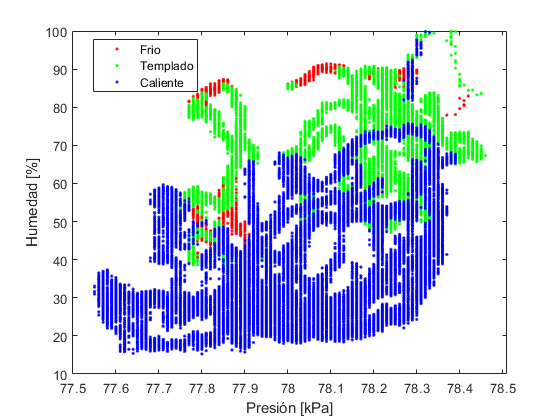


figure
gscatter(atmosfera_noNaNs.Pres_kpa, atmosfera_noNaNs.Hum_perc, atmosfera_noNaNs.temp_cats)
xlabel("Presión [kPa]")
ylabel("Humedad [%]")

## Pareto chart

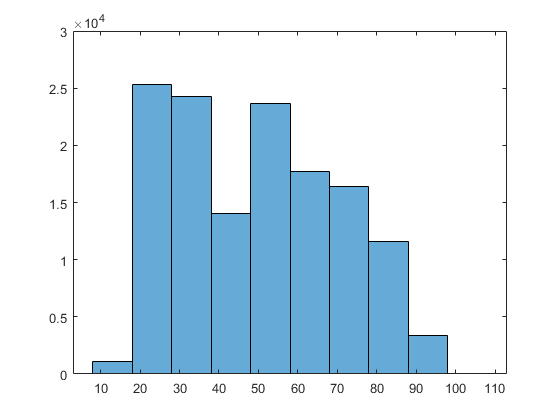

h=histogram(atmosfera_noNaNs.Hum_perc,10);

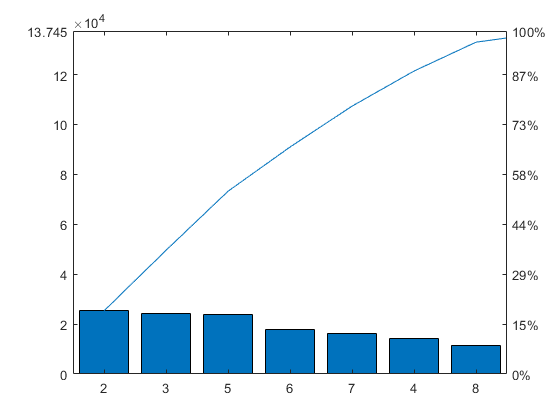

cuentas=h.BinCounts;

figure
pareto(cuentas)